%Pretty condition
u = 0;
D = 4;

t_start = 0;
t_final = 0.1;
dt = 0.001;
n_step_time = (t_final-t_start)/dt;

x_start = 0;
x_final = 10;
dx = 0.1;
n_step_space = (x_final - x_start)/dx+1;

x = linspace(x_start, x_final, n_step_space);
t = linspace(t_start, t_final, n_step_time);

alpha = u*dt/(2*dx);
beta = D*dt/(dx^2);


if (D*dt/(dx^2) <= 1/2 )
   disp("Stability respected!")
else
    disp("Stability not respected!")
end

Stability respected!


% Condizioni di Dirichlet
% Sono gia rispettate perche la matrice è di tutti 0
T = zeros(n_step_space,n_step_time);
%for i = 2:n_step_space-1
%    T(i, 1) = exp(-(dx*(i-(n_step_space)/2))^2);
%end

for i = 1:n_step_space
    T(i, 1) = (i-1)*dx;
end

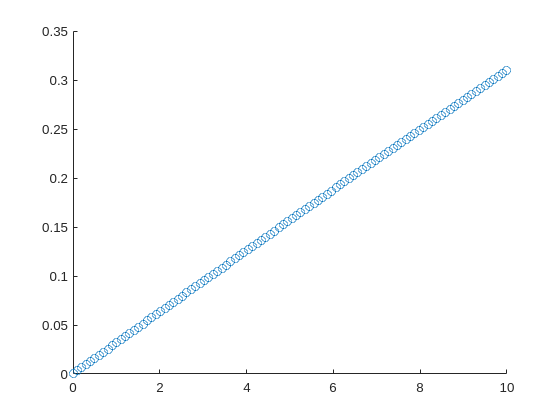

scatter(x, T(:,1))    

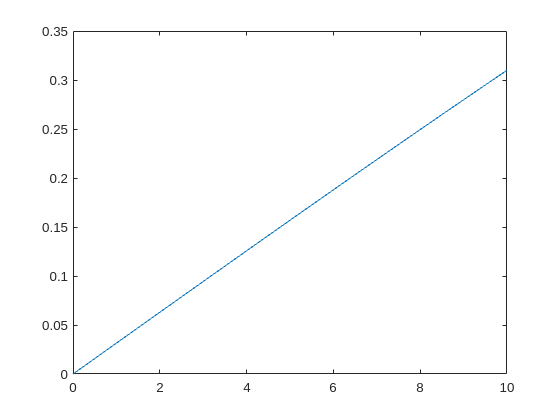

plot(x, T(:,1))

% Dirichlet condition solver
% i indice per lo spazio
% j indice per il tempo
for j = 2:n_step_time
    for i = 2:n_step_space-1
        A = alpha*(T(i+1,j-1) - T(i-1,j-1));
        B = beta*( T(i+1, j-1) - 2*T(i, j-1) + T(i-1, j-1) );
        T(i,j) = T(i, j-1) - A + B;
    end
end


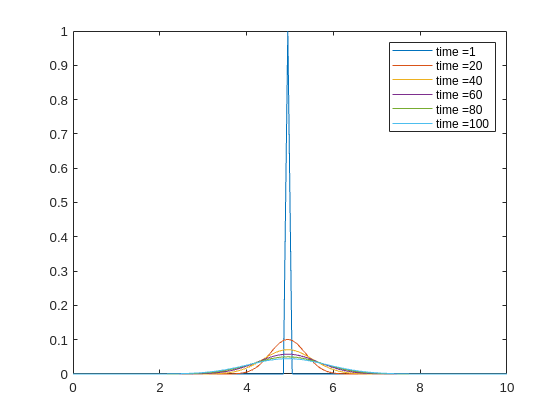

Legend=cell(6,1);
Legend{1}=strcat('time = ', num2str(1));

for j = 2:6
    Legend{j}=strcat('time = ', num2str((j-1)*20));
end

plot(x, T(:, 1))
hold on
for j = 1:5
    plot(x, T(:,(j)*20));
    hold on
end
legend(Legend)
hold off

%Stesse condizioni iniziali del problema%
T_sol_exact = zeros(n_step_space, n_step_time);
for i = 2:n_step_space-1
    T_sol_exact(i, 1) = exp(-(dx*(i-(n_step_space)/2))^2);
end



%Metto la soluzione esatta%
k_max = 10;

for j = 2:n_step_time
    for i = 2:n_step_space-1
        for k = 1:k_max
            

        end
    end
end